clear all;close all;clc

doTraining = true;
if ~doTraining && ~exist("ssdResNet50VehicleExample_22b.mat","file")
    disp("Downloading pretrained detector (44 MB)...");
    pretrainedURL = "https://www.mathworks.com/supportfiles/vision/data/ssdResNet50VehicleExample_22b.mat";
    websave("ssdResNet50VehicleExample_22b.mat",pretrainedURL);
end

% Folder containing images and XML files
imageFolder = 'C:\Users\varsh\Downloads\EOC_mfc';
xmlFolder = imageFolder;  % Assuming XML files are in the same folder

% Get a list of all images (assuming JPG format)
imageFiles = dir(fullfile(imageFolder, '*.jpg'));
numImages = length(imageFiles);

% Preallocate cell arrays for filenames and bounding boxes
imageFilenames = cell(numImages, 1);
vehicleLabels = cell(numImages, 1);

% Loop through all images
for i = 1:numImages
    % Get image filename
    imageFilenames{i} = fullfile(imageFolder, imageFiles(i).name);
    
    % Corresponding XML annotation file
    [~, name, ~] = fileparts(imageFiles(i).name);
    xmlFile = fullfile(xmlFolder, [name, '.xml']);
    
    % Check if XML file exists
    if isfile(xmlFile)
        % Read XML file
        xmlDoc = xmlread(xmlFile);
        
        % Parse XML to extract bounding boxes
        objects = xmlDoc.getElementsByTagName('object');
        bbox = [];
        for j = 0:objects.getLength-1
            objItem = objects.item(j);
            bndbox = objItem.getElementsByTagName('bndbox').item(0);
            
            % Extract bounding box coordinates
            xmin = str2double(bndbox.getElementsByTagName('xmin').item(0).getTextContent);
            ymin = str2double(bndbox.getElementsByTagName('ymin').item(0).getTextContent);
            xmax = str2double(bndbox.getElementsByTagName('xmax').item(0).getTextContent);
            ymax = str2double(bndbox.getElementsByTagName('ymax').item(0).getTextContent);
            
            % Convert to (x, y, width, height)
            bbox = [bbox; xmin, ymin, xmax - xmin, ymax - ymin];
        end
    else
        disp(['Missing XML for: ', imageFilenames{i}]);
        bbox = []; % If XML is missing, keep empty
    end
    
    % Store label data
    vehicleLabels{i} = bbox;
end

% Create the dataset table
dataset = table(imageFilenames, vehicleLabels, 'VariableNames', {'imageFilename', 'vehicle'});

% Display the dataset
disp(dataset);

                      imageFilename                             vehicle      
    __________________________________________________    ___________________

    {'C:\Users\varsh\Downloads\EOC_mfc\img (1).jpg'  }    { 5×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (10).jpg' }    { 3×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (100).jpg'}    { 3×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (101).jpg'}    { 3×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (102).jpg'}    { 3×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (103).jpg'}    { 2×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (104).jpg'}    {[ 17 246 219 318]}
    {'C:\Users\varsh\Downloads\EOC_mfc\img (105).jpg'}    {[  1 241 231 343]}
    {'C:\Users\varsh\Downloads\EOC_mfc\img (106).jpg'}    { 6×4 double      }
    {'C:\Users\varsh\Downloads\EOC_mfc\img (107).jpg'}    { 5×4 double   

save('accident_prone_dataset.mat', 'dataset');
load('accident_prone_dataset.mat');
open('accident_prone_dataset.mat');

splitRatio = 0.6;
numImages = height(dataset);

% Generate random indices for shuffling
rng(0); % For reproducibility
shuffledIndices = randperm(numImages);

% Compute the split index
numTrain = round(splitRatio * numImages);

% Get training and testing indices
trainIndices = shuffledIndices(1:numTrain);
testIndices = shuffledIndices(numTrain+1:end);

% Create training and testing datasets
trainingData = dataset(trainIndices, :);
testData = dataset(testIndices, :);

% Display sizes
fprintf('Training Data: %d images\n', height(trainingData));

Training Data: 180 images


fprintf('Testing Data: %d images\n', height(testData));

Testing Data: 120 images


imdsTrain = imageDatastore(trainingData{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingData(:,"vehicle"));

imdsTest = imageDatastore(testData{:,"imageFilename"});
bldsTest = boxLabelDatastore(testData(:,"vehicle"));

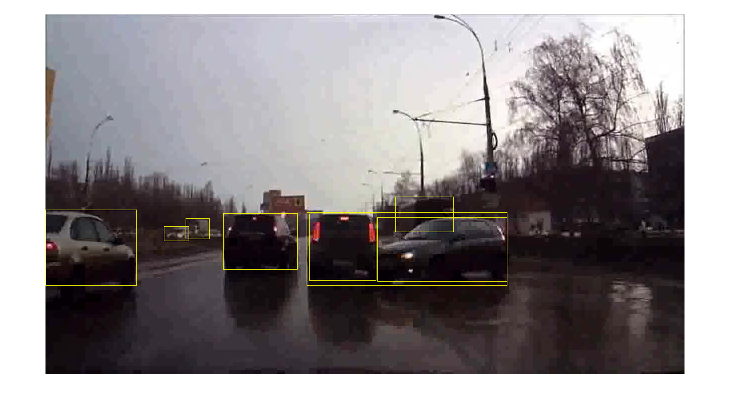

trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest, bldsTest);
data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

% Ensure the Deep Learning Toolbox Model for ResNet-50 is installed
if exist('resnet50', 'file') ~= 2
    error(['ResNet-50 requires the Deep Learning Toolbox Model for ResNet-50 ', ...
           'support package. Install it using the Add-On Explorer or use resnet50(''Weights'', ''none'').']);
end

% Try to load ResNet-50
try
    net = resnet50(); % Load pretrained model
    disp('Loaded pretrained ResNet-50 network.');
catch
    warning('Pretrained ResNet-50 is not available. Using untrained network.');
    net = resnet50('Weights', 'none'); % Load untrained model
    disp('Loaded untrained ResNet-50 network.');
end

Loaded pretrained ResNet-50 network.



% Check the network type and properly convert it
if isa(net, 'DAGNetwork')
    % Pretrained ResNet-50 case
    lgraph = layerGraph(net)
elseif isa(net, 'dlnetwork')
    % Untrained ResNet-50 case (dlnetwork cannot be directly converted)
    layers = layerGraph(net.Layers); % Extract layers and create layerGraph
    lgraph = layers;
else
    error(['Unexpected network type: ', class(net), '. Ensure ResNet-50 is correctly loaded.']);
end

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]



% Modify input size if needed
inputSize = [300 300 3]; % Custom input size
lgraph = replaceLayer(lgraph, 'input_1', imageInputLayer(inputSize, 'Name', 'input_1'))

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]



% Define class names
classNames = "vehicle"

classNames = "vehicle"


% Display success message
disp('ResNet-50 successfully loaded and converted to layer graph.');

ResNet-50 successfully loaded and converted to layer graph.


class(net)

ans = 'DAGNetwork'

% Find layer index of "activation_40_relu"
idx = find(ismember({lgraph.Layers.Name},"activation_40_relu"));

% Remove all layers after "activation_40_relu" layer
removedLayers = {lgraph.Layers(idx+1:end).Name};
ssdLayerGraph = removeLayers(lgraph,removedLayers);

weightsInitializerValue = "glorot";
biasInitializerValue = "zeros";

% Append Extra layers on top of a base network.
extraLayers = [];

% Add conv6_1 and corresponding reLU
filterSize = 1;
numFilters = 256;
numChannels = 1024;
conv6_1 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Name = "conv6_1", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu6_1 = reluLayer(Name = "relu6_1");
extraLayers = [extraLayers; conv6_1; relu6_1];

% Add conv6_2 and corresponding reLU
filterSize = 3;
numFilters = 512;
numChannels = 256;
conv6_2 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Padding = iSamePadding(filterSize), ...
    Stride = [2, 2], ...
    Name = "conv6_2", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu6_2 = reluLayer(Name = "relu6_2");
extraLayers = [extraLayers; conv6_2; relu6_2];

% Add conv7_1 and corresponding reLU
filterSize = 1;
numFilters = 128;
numChannels = 512;
conv7_1 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Name = "conv7_1", ...
    WeightsInitializer = weightsInitializerValue,...
    BiasInitializer = biasInitializerValue);
relu7_1 = reluLayer(Name = "relu7_1");
extraLayers = [extraLayers; conv7_1; relu7_1];

% Add conv7_2 and corresponding reLU
filterSize = 3;
numFilters = 256;
numChannels = 128;
conv7_2 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Padding = iSamePadding(filterSize), ...
    Stride = [2, 2], ...
    Name = "conv7_2", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu7_2 = reluLayer(Name = "relu7_2");
extraLayers = [extraLayers; conv7_2; relu7_2];

% Add conv8_1 and corresponding reLU
filterSize = 1;
numFilters = 128;
numChannels = 256;
conv8_1 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Name = "conv8_1", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu8_1 = reluLayer(Name = "relu8_1");
extraLayers = [extraLayers; conv8_1; relu8_1];

% Add conv8_2 and corresponding reLU
filterSize = 3;
numFilters = 256;
numChannels = 128;
conv8_2 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Name = "conv8_2", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu8_2 = reluLayer(Name ="relu8_2");
extraLayers = [extraLayers; conv8_2; relu8_2];

% Add conv9_1 and corresponding reLU
filterSize = 1;
numFilters = 128;
numChannels = 256;
conv9_1 = convolution2dLayer(filterSize, numFilters, NumChannels = numChannels, ...
    Padding = iSamePadding(filterSize), ...
    Name = "conv9_1", ...
    WeightsInitializer = weightsInitializerValue, ...
    BiasInitializer = biasInitializerValue);
relu9_1 = reluLayer("Name", "relu9_1");
extraLayers = [extraLayers; conv9_1; relu9_1];

if ~isempty(extraLayers)
    lastLayerName = ssdLayerGraph.Layers(end).Name;
    ssdLayerGraph = addLayers(ssdLayerGraph, extraLayers);
    ssdLayerGraph = connectLayers(ssdLayerGraph, lastLayerName, extraLayers(1).Name)
end

ssdLayerGraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {1×0 cell}
         Layers: [155×1 nnet.cnn.layer.Layer]
    Connections: [167×2 table]


detNetworkSource = ["activation_22_relu", "activation_40_relu", "relu6_2", "relu7_2", "relu8_2"]

detNetworkSource = 1×5 string array
    "activation_22_relu"    "activation_40_relu"    "relu6_2"    "relu7_2"    "relu8_2"


anchorBoxes = {[60,30;30,60;60,21;42,30];...
               [111,60;60,111;111,35;64,60;111,42;78,60];...
               [162,111;111,162;162,64;94,111;162,78;115,111];...
               [213,162;162,213;213,94;123,162;213,115;151,162];...
               [264,213;213,264;264,151;187,213]};

detector = ssdObjectDetector(ssdLayerGraph,classNames,anchorBoxes,DetectionNetworkSource=detNetworkSource,InputSize=inputSize,ModelName='ssdVehicle');

augmentedTrainingData = transform(trainingData,@augmentData)

augmentedTrainingData =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "dat"    "asc"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
                Transforms: {@augmentData}
               IncludeInfo: [0]


function sanitizedBoxes = helperSanitizeBoxes(bboxes)
    % Ensure bounding boxes are in a valid format
    if isempty(bboxes)
        sanitizedBoxes = zeros(0,4); % Empty bounding box array
    else
        sanitizedBoxes = max(0, bboxes); % Ensure non-negative values
    end
end


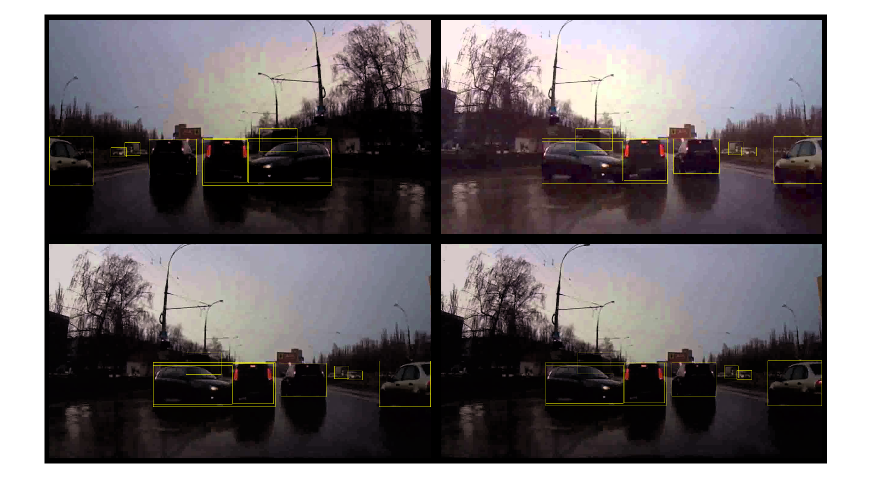

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    
    % Ensure bounding boxes are sanitized
    data{2} = helperSanitizeBoxes(data{2});
    
    augmentedData{k} = insertShape(data{1}, 'Rectangle', data{2});
    reset(augmentedTrainingData);
end

figure;
montage(augmentedData, 'BorderSize', 10);

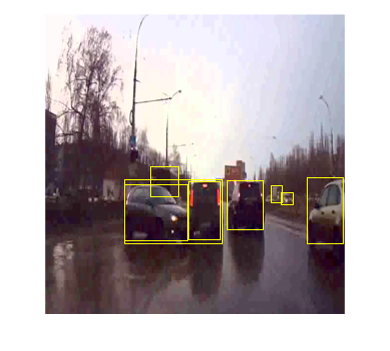

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
data = read(preprocessedTrainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure;
imshow(annotatedImage);

options = trainingOptions('sgdm', ...
        MiniBatchSize = 16, ....
        InitialLearnRate = 1e-3, ...
        LearnRateSchedule = 'piecewise', ...
        LearnRateDropPeriod = 30, ...
        LearnRateDropFactor =  0.8, ...
        MaxEpochs = 20, ...
        VerboseFrequency = 50, ...        
        CheckpointPath = tempdir, ...
        Shuffle = 'every-epoch');

% Control flag for training
doTraining = true;  % Set to false if you want to load a pre-trained model

if doTraining
    % Train the SSD detector
    [detector, info] = trainSSDObjectDetector(preprocessedTrainingData, detector, options);
else
    % Load pre-trained detector

    pretrained = load('ssdResNet50VehicleExample_22b.mat');
    detector = pretrained.detector;
end

*************************************************************************
Training an SSD Object Detector for the following object classes:

* vehicle

Training on single CPU.
Initializing input data normalization.
|=======================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|=======================================================================================================|
|       1 |           1 |       00:00:09 |      46.7676 |       44.69% |         2.23 |          0.0010 |
|       5 |          50 |       00:06:37 |       4.2198 |       99.69% |         1.18 |          0.0010 |
|      10 |         100 |       00:12:45 |       3.2873 |       99.64% |         1.06 |          0.0010 |
|      14 |         150 |       00:18:55 | 

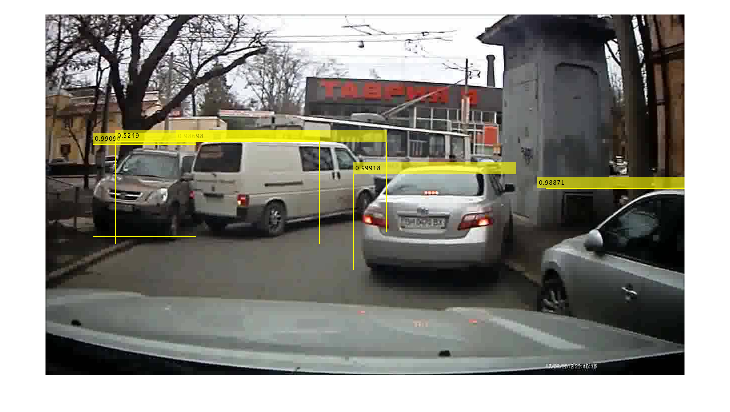

% Read a sample image from the test data
data = read(testData); % Read data from the CombinedDatastore
I = data{1};           % Extract the image
bbox = data{2};        % Extract bounding boxes

% Run object detection on the image

for scale = [0.5, 1.0, 1.5] 
    resizedImage = imresize(I, scale); 
     [bbox, scores, labels] = detect(detector, resizedImage);
     % Rescale bounding boxes back to original image
     bbox = bbox / scale;  
 end

% Ensure scores is defined before inserting annotations
if isempty(scores)
    disp('No objects detected.');
else
    % Annotate the detected objects on the image
    I = insertObjectAnnotation(I, 'rectangle', bbox, scores);
end

% Display the image with annotations
figure;
imshow(I)

TESTING

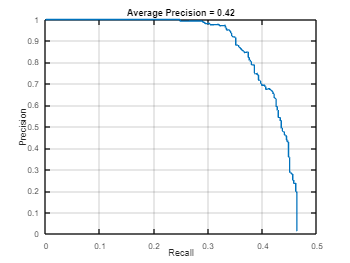

preprocessedTestData = transform(testData,@(date)preprocessData(date,inputSize));
detectionThreshold = 0.01;
detectionResults = detect(detector, preprocessedTestData, ...
    Threshold=detectionThreshold, ...
    MiniBatchSize = 32);
metrics = evaluateObjectDetection(detectionResults,preprocessedTestData);
classID = 1;
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};
figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',metrics.ClassMetrics.mAP(classID)));

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
B = cell(size(A));
I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        Contrast = 0.2,...
        Hue = 0,...
        Saturation = 0.1,...
        Brightness = 0.2);
end
% Randomly flip and scale image.
tform = randomAffine2d(XReflection = true, Scale = [1 1.1]);  
rout = affineOutputView(sz,tform, BoundsStyle = 'CenterOutput');    
B{1} = imwarp(I,tform,OutputView = rout);
% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
A{2} = helperSanitizeBoxes(A{2});    
% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,OverlapThreshold = 0.25);    
B{3} = A{3}(indices);  
% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));
% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
data{2} = helperSanitizeBoxes(data{2});
% Resize boxes.
data{2} = bboxresize(data{2},scale);
end

function p = iSamePadding(FilterSize)
    p = floor(FilterSize / 2);
end
